- **Для первой подсистемы (стабилизирующий регулятор) вычисляется матрица линейных стационарных обратных связей К в соответствии работой №8.**

A = [2 6; 1 0];
B = [4; 1];
C =[2 0];
t_p = 0.3;
sigma = 5;
t_p1 = 2.9;

Q = eye(2);
R=1;
[K,P]=lqr(A+0*Q,B,Q,R/2);
K = inv(R)*B'*P

K =     1.0365    1.0831


Используем полином Баттерворта

w = t_p1/t_p

w = 9.6667

syms s  
a_s = sym2poly(s^2 + sqrt(2)*w*s + w^2)

a_s =     1.0000   13.6707   93.4444


p = sym2poly(s^2 + sqrt(2)*w*s + w^2);
G = [0 -a_s(3); 1 -a_s(2)]

G =          0  -93.4444
    1.0000  -13.6707


H = [1 1];

Найдем матрицу М, решив уравнение $\textrm{MG}-\textrm{AM}=\textrm{BH}$

syms M_solve [2 2]
M_solve = solve(M_solve*G-A*M_solve == B*H);
M = [sym2poly(M_solve.M_solve1_1)  sym2poly(M_solve.M_solve1_2); sym2poly(M_solve.M_solve2_1) sym2poly(M_solve.M_solve2_2)]

M =    -0.4745    2.3731
   -0.1130    0.5255


**2. Для второй подсистемы (наблюдатель), описание которой определяется матрицей **$F_н$ **, формируются матрицы эталонной модели **$G_н \;и\;H_н$  ***,***** предназначенные для синтеза наблюдателя, то есть матрица строится на основе требуемых корней или коэффициентов характеристического полинома, а матрица **$H_н$ **находится из условия полной наблюдаемости эталонной модели. Размерность выбрать в соответствии с вариантом задания из таблицы №9.1.**

Размерность наблюдателя: полная

D = 6; 
t_pn = 0.3;
sigma_n = 5;
s = tf('s');
U = [C; C*A]

U =      2     0
     4    12


if (rank(U) ~= rank(A))
    disp('матрица НЕнаблюдаема')
else
    disp('матрицы полностью наблюдаемы')
end

матрицы полностью наблюдаемы


2.1. При синтезе наблюдателя полной размерности, учитывая принцип

дуальности для управляемости и наблюдаемости, задача нахождения

матрицы входов L сводится к решению матричного уравнения типа

Сильвестра относительно матрицы Мн вида:


$$M_n G_n -A^T M_n =C^T H_n$$


С последующим расчетом матрицы входов наблюдателя полной

размерности :


$$L^T =-H_n M_n^{-1}$$


syms lambda
t_p1 = 2.9;
w = t_p1/t_p

w = 9.6667

D1_lambda = lambda^2+1.414*w*lambda+w^2;
lambda = solve(D1_lambda==0);
D1_lambda = sym2poly(D1_lambda)

D1_lambda =     1.0000   13.6687   93.4444


lambda = [sym2poly(lambda(2, 1)); sym2poly(lambda(1, 1))]

lambda =   -6.8343 + 6.8364i
  -6.8343 - 6.8364i


G_n = [0 -D1_lambda(3); 1 -D1_lambda(2)]

G_n =          0  -93.4444
    1.0000  -13.6687


H = [1 1];
M0 = sylv(-A', G_n, C'*H)

M0 =    -0.2712    1.5934
    0.1357   -1.6270


L2 = (-H*inv(M0))'

L2 =     7.8343
    8.2870


**3. Синтезировать наблюдатель полной размерности, используя представление объекта в каноническом наблюдаемом базисе, решив следующую систему матричных уравнений:**

Найдем характеристический полином ОУ:

syms lambda
D_lambda = det(A-eye(2)*lambda)

$$D\_lambda = \lambda^{2}-2\,\lambda -6$$

D_lambda = sym2poly(D_lambda);
A_h = [0 -D_lambda(3); 1 -D_lambda(2)]

A_h =      0     6
     1     2


C_h = [0 1]

C_h =      0     1


a_s = s^2 + sqrt(2)*w*s + w^2

a_s =
 
  s^2 + 13.67 s + 93.44
 
Continuous-time transfer function.



F_h = [0 -w^2; 1 sqrt(2)*w]

F_h =          0  -93.4444
    1.0000   13.6707


K = -H*M0^-1

K =     7.8343    8.2870


syms p11 p12 p21 p22 l1 l2
P = [p11 p12; p21 p22];
L = [l1; l2];
P1 = P^-1;
eqn1 = A_h==P*A*inv(P);
eqn2 = C_h==C*inv(P);
eqn3 = inv(P)*F_h*P == A - L*C;
sol = solve([eqn1; eqn2; eqn3], [p11; p12; p21; p22; l1; l2]);
P = double([sol.p11 sol.p12; sol.p21 sol.p22])

P =      0    12
     2     0


L = double([sol.l1; sol.l2])

L =    -5.8354
    8.2870


**4. Проведение проверочного расчета, который основан на построении расположения корней первой подсистемы системы на комплексной плоскости и вычислением корней характеристического полинома второй подсистемы и сравнение их с корнями требуемого характеристического полинома**

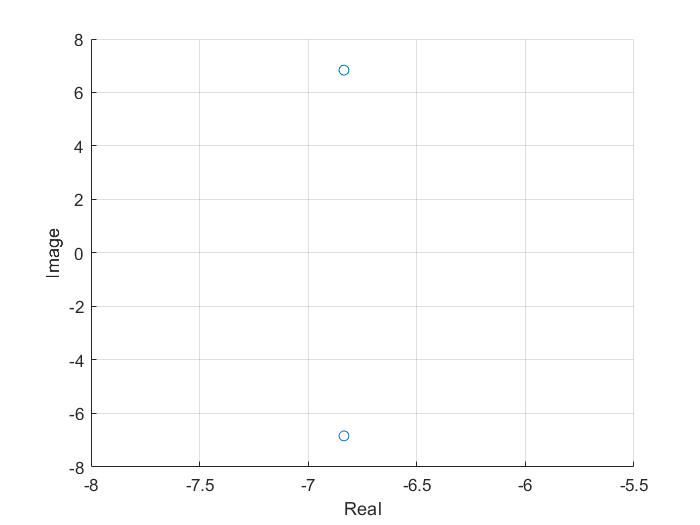

r = roots(p);
scatter(real(r),imag(r))
grid on
xlabel('Real')
ylabel('Image')

**5. Провести компьютерное моделирование замкнутой системы.**

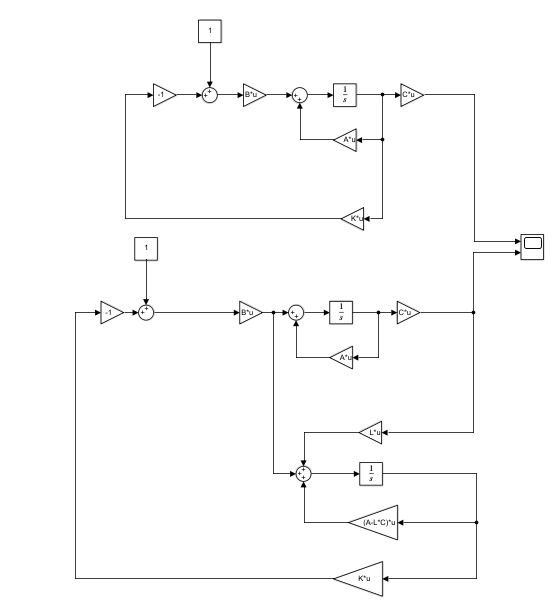

**Первая подсистема: **

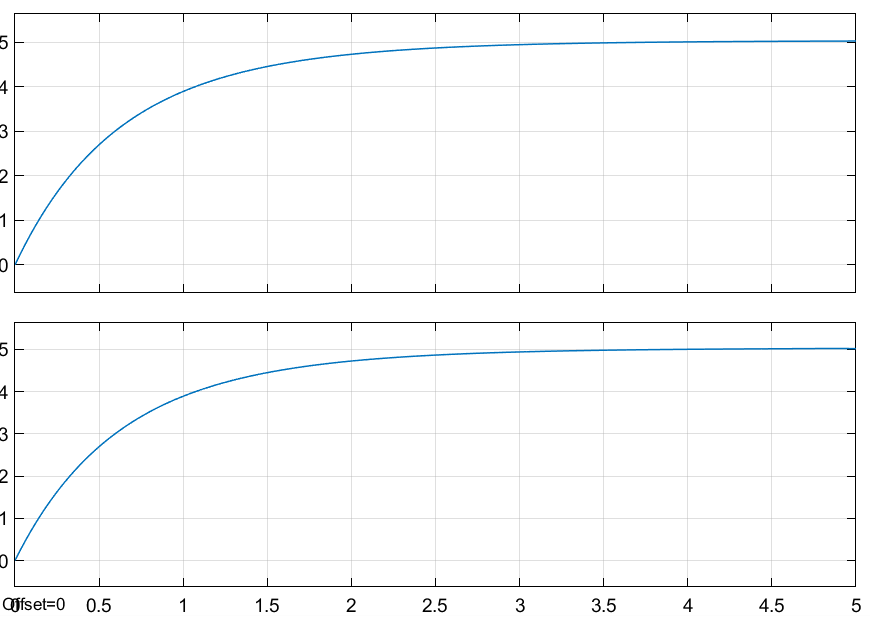

**Вторая подсистема:**

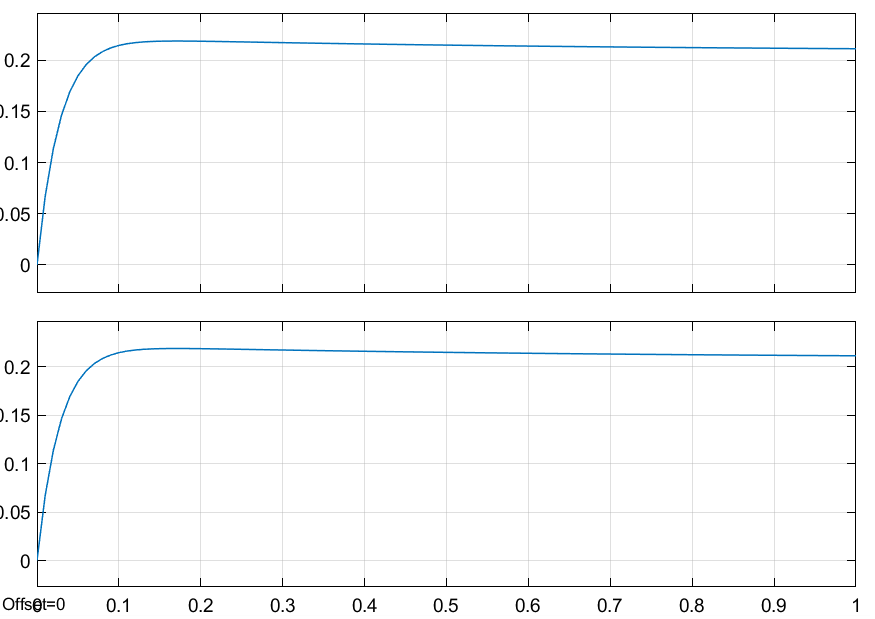

**Вывод**

В ходе выполнения данной лабораторной работы были изучены принципы построения наблюдателей неизмеряемого состояния. Был получен характеристический полином, соответствующий желаемым показателям качества, а также синтезирован наблюдатель неизмеряемого состояния двумя методами: методом канонических форм и решением уравнения типа Сильвестра.